# Calculation Results Overview

## Eigenvalue

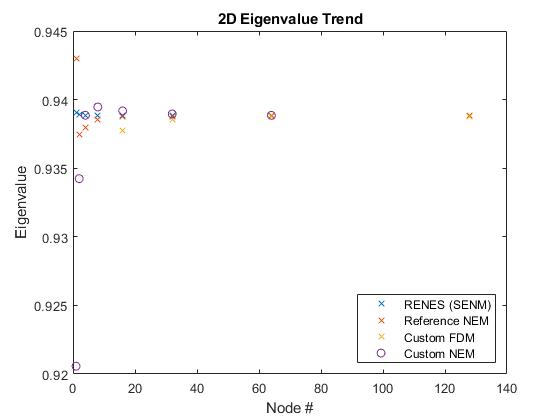

nodes = [1,2,4,8,16,32,64,128];
RENUS = [0.9390498,0.9388877,0.9388394,0.938821,0.9388188,0.9388188,0.9388189,nan];
NEM_ref = [0.942988,0.937463,0.937942,0.938524,0.938738,0.938798,0.938813,0.938817];
FDM_cus = [nan,nan,nan,nan,0.9377386,0.9385135,0.9387344,0.9387916];
NEM_cus = [0.920563121,0.934235679,0.938856851,0.939462807,0.9391780510,0.9389520238,0.9388529554,nan];

figure
plot(nodes,RENUS,'x',nodes,NEM_ref,'x',nodes,FDM_cus,'x',nodes,NEM_cus,'o')
title('2D Eigenvalue Trend')
xlabel('Node #')
ylabel('Eigenvalue')
legend('RENES (SENM)','Reference NEM','Custom FDM','Custom NEM','Location','southeast')

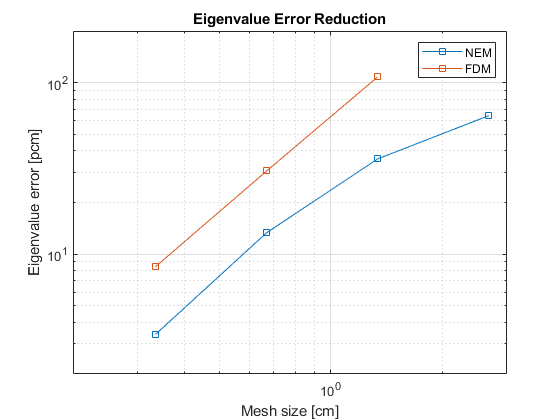

NEM_cus = [nan,nan,nan,0.939462807,0.9391780510,0.9389520238,0.9388529554,nan];
meshSize = 21.42./nodes;
err_NEM = abs(NEM_cus - RENUS)*1E5;
err_FDM = abs(FDM_cus - RENUS)*1E5;
figure
loglog(meshSize,err_NEM,'-s',meshSize,err_FDM,'-s')
title('Eigenvalue Error Reduction')
xlabel('Mesh size [cm]')
ylabel('Eigenvalue error [pcm]')
xlim([0.2,3])
ylim([2E0,2E2])
grid on
legend('NEM','FDM')